# Visualise conserved moieties in dopaminergic neuronal metabolism

tutorial_initConservedMoietyPaths

projectDir = '~/work/sbgCloud/programExperimental/projects/tracerBased'

dataDir = '~/work/sbgCloud/programExperimental/projects/tracerBased/data/'

softwareDir = '~/work/sbgCloud/programExperimental/projects/tracerBased/software/'

visDataDir = '~/work/sbgCloud/programExperimental/projects/tracerBased/data/visualisation/'

resultsDir = '~/work/sbgCloud/programExperimental/projects/tracerBased/results/iDopaNeuroC_ConservedMoieties/'

rxnfileDir = '~/work/sbgCloud/code/fork-ctf/modelDatabases/iDNc/rxns/atomMapped'

% if ~recompute
%     load([resultsDir  modelName '_ConservedMoietiesAnalysis.mat'])
%     return
% end

Load the dopaminergic neuronal metabolic model

load([dataDir filesep 'models' filesep modelName '.mat'])

Identify the stoichiometrically consistent subset of the model

massBalanceCheck=1;
printLevel=1;
[SConsistentMetBool, SConsistentRxnBool, SInConsistentMetBool, SInConsistentRxnBool, unknownSConsistencyMetBool, unknownSConsistencyRxnBool, model]...
    = findStoichConsistentSubset(model,massBalanceCheck,printLevel);

--- findStoichConsistentSubset START ----
--- Summary of stoichiometric consistency ----
  1594	  2423	 totals.
     0	   319	 heuristically external.
  1594	  2104	 heuristically internal:
  1594	  2103	 ... of which are stoichiometrically consistent.
     0	     0	 ... of which are stoichiometrically inconsistent.
     0	     1	 ... of which are of unknown consistency.
---
     0	     1	 heuristically internal and stoichiometrically inconsistent or unknown consistency.
     4	     1	 ... of which are elementally imbalanced (inclusively involved metabolite).
     0	     1	 ... of which are elementally imbalanced (exclusively involved metabolite).
  1594	  2103	 Confirmed stoichiometrically consistent by leak/siphon testing.
--- findStoichConsistentSubset END ----


### Metabolite connectity

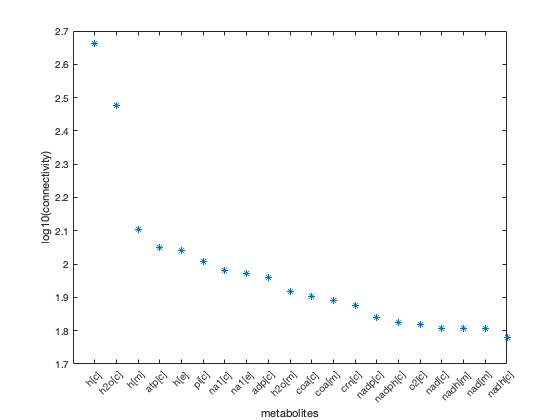

param.n=20;
[rankMetConnectivity,rankMetInd,rankConnectivity] = rankMetabolicConnectivity(model,param);

### Load atomically resolved models & conserved moiety analysis

Load the atomically resolved models derived from identifyConservedMoieties.m

if 0
    load([resultsDir 'iDopaMoieties_noChecks.mat'])
else
    load([resultsDir  modelName '_ConservedMoietiesAnalysis.mat'])
end

### Transitive moiety, of sufficient mass, with moderate incidence

isTransititiveMoiety= strcmp('Transitive',moietyTypes);
isModerateIncidence = moietyIncidence>=10 & moietyIncidence<=100;
isSufficientMass = moietyMasses > 2;
isSufficientMinimalMassFraction = minimalMassFraction > 0.1;
interestingMoiety = isTransititiveMoiety & isModerateIncidence & isSufficientMass & isSufficientMinimalMassFraction;
C = cell(nnz(interestingMoiety),9);
n=1;
for i=1:size(arm.L,1)
    if interestingMoiety(i)
        ind = find(strcmp(minimalMassMetabolite{i},model.mets));
        C(n,1:9) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),minimalMassMetabolite{i},model.metNames{ind},model.metFormulas{ind},minimalMassFraction(i)};
        n=n+1;
    end
end

C=sortrows(C,9,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moiety_formula','mass','Minimal_mass_metabolite','Name','Formula','Mass_fraction'};
size(T,1)

ans =     10


disp(T)

    index    metabolites    rxns    moiety_formula         mass         Minimal_mass_metabolite                  Name                      Formula          Mass_fraction  
    _____    ___________    ____    ______________    ______________    _______________________    _________________________________    ______________    _________________

     28          59         228     {'S'        }        31.97207069        {'HC00250[e]'}         {'Hydrosulfide'                 }    {'HS'        }     0.96944123048198
     56          22          60     {'C5HA2O5'  }     140.9823981426        {'HC02056[c]'}         {'1,2-Diacylglycerol-Ld-Pc-Pool'}    {'C5H6O5R2'  }    0.965490531488018
     

### Recon3Map

Import Recon3Map

if ~exist('Recon3xml','var')   
    [Recon3xml, Recon3map] = transformXML2Map([visDataDir 'reconMap3d_allin.xml']);
end
if 0
    transformMap2XML(Recon3xml,Recon3map,[resultsDir 'Recon3map.xml']);
end

### Compare the reactions in the specified metabolic model and Recon3Map

The function `checkCDerrors` gives four outputs summarising all possible discrepancies between model and map.

printLevel=0;
[diffReactions, diffMetabolites, diffReversibility, diffFormula] = checkCDerrors(Recon3map, model,printLevel);

Four outputs are obtained from this function:

"`diffReactions`" summarises present and absent reactions between model and map.

Display the internal reactions in the model that are not present in the map.

bool=ismember(diffReactions.extraRxnModel,model.rxns(model.SConsistentRxnBool));
nnz(bool)

ans =     34


disp(diffReactions.extraRxnModel(bool))

    {'ACER12r'     }
    {'ACITL'       }
    {'ATPM'        }
    {'ATPS4m'      }
    {'CE1554t'     }
    {'CE1554tm'    }
    {'COAtp'       }
    {'GLUPROASCT1' }
    {'GLUVESSEC'   }
    {'GLUt6'       }
    {'GLYLEUHYDROc'}
    {'GLYPROPRO1c' }
    {'H2O2itr'     }
    {'LEULEULAPc'  }
    {'LST4EXPTDhc' }
    {'LST4EXPthc'  }
    {'LSTNM7TDhc'  }
    {'LSTNM7thc'   }
    {'LSTNRATt'    }
    {'LSTNtd'      }
    {'MI1Pt'       }
    {'NADH2_u10m'  }
    {'PVSHtu'      }
    {'PVStep'      }
    {'TMDOATPtsc'  }
    {'TMDOATtev'   }
    {'TMDOATthc'   }
    {'TMDtd'       }
    {'TRPGLYLEUr'  }
    {'TRPILELYSr'  }
    {'acglua'      }
    {'acileua'     }
    {'acleua'      }
    {'acthra'      }



"`diffMetabolites`" summarises present and absent metabolites. 

***NOTE!**** Note that having more metabolites and reactions in the COBRA model is normal since the model can contain more elements than the map. On the other hand, the map should only contain elements present in the model.*

 "`diffReversibility`" summarises discrepancies in defining the reversibility of reactions.

The last output "`diffFormula"` summarises discrepancies in reactions formulae (kinetic rates) and also lists duplicated reactions.

### Create a map of the model

Remove some reactions from the map

rxnRemoveList = diffReactions.extraRxnsMap;

Remove non-dopaminergic neuronal reactions from the map

[modelNameXml,modelNameMap] = removeMapReactions(Recon3xml, Recon3map,rxnRemoveList);

Remove pathway labels from the map

specRemoveType='UNKNOWN';
specRemoveList=[];
printLevel=0;
[modelNameXml,modelNameMap,specNotInMap] = removeMapSpecies(modelNameXml,modelNameMap,specRemoveList,specRemoveType,printLevel);

Remove highly connected metabolites from the map

specRemoveList={'h[c]';'h[l]';'h[e]';'h[r]';'h2o[c]';'h2o[l]';'h20[e]';'pi[c]';'adp[c]';'nadph[c]';'nadh[c]';'nadph[m]';'nadh[m]'};
[xmlStruct,map,specNotInMap] = removeMapSpeciesOnly(modelNameXml,modelNameMap,specRemoveList,specRemoveType,printLevel);

Export the model map

transformMap2XML(modelNameXml,modelNameMap,[resultsDir modelName '_CD.xml']);

Elapsed time is 134.916364 seconds.


### Nicotinate moiety

ind = 9;% Nicotinate moiety
mBool=arm.L(min(ind,size(arm.L,1)),:)~=0;
nnz(mBool)

ans =      2


rBool = getCorrespondingCols(model.S, mBool, true(size(model.S,2),1), 'inclusive');
nnz(rBool)

ans =     64


Metabolites

bool=mBool;
C = cell(nnz(bool),5);
n=1;
for i=1:size(model.S,1)
    if bool(i)
        C(n,1:5) = {i,model.mets{i},model.metNames{i},model.metFormulas{i},metMasses(i)};
        n=n+1;
    end
end
C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','met','name','formula','mass'};
disp(T)

    index        met                             name                               formula              mass     
    _____    ___________    _______________________________________________    _________________    ______________

     50      {'nadh[m]'}    {'Nicotinamide Adenine Dinucleotide - Reduced'}    {'C21H27N7O14P2'}    663.1091216325
     51      {'nad[m]' }    {'Nicotinamide Adenine Dinucleotide'          }    {'C21H26N7O14P2'}    662.1012966004



Reactions

formulas = printRxnFormula(model, model.rxns(rBool));

2OXOADOXm	nad[m] + 2oxoadp[m] + coa[m] 	->	nadh[m] + co2[m] + glutcoa[m] 
34HPLFM	h[m] + nadh[m] + 34hpp[m] 	->	nad[m] + 34hpl[m] 
AASAD3m	h2o[m] + nad[m] + L2aadp6sa[m] 	->	2 h[m] + L2aadp[m] + nadh[m] 
AKGDm	akg[m] + nad[m] + coa[m] 	->	nadh[m] + co2[m] + succoa[m] 
ALDD2xm	h2o[m] + nad[m] + acald[m] 	->	2 h[m] + nadh[m] + ac[m] 
BDHm	nad[m] + bhb[m] 	<=>	h[m] + nadh[m] + acac[m] 
FAOXC161802m	4 h2o[m] + 4 nad[m] + 4 coa[m] + 3 fad[m] + hdd2coa[m] 	->	4 h[m] + 4 nadh[m] + 4 accoa[m] + 3 fadh2[m] + occoa[m] 
FAOXC16180m	4 h2o[m] + 4 nad[m] + 4 coa[m] + 3 fad[m] + hdcoa[m] 	->	4 h[m] + 4 nadh[m] + 4 accoa[m] + 3 fadh2[m] + occoa[m] 
FAOXC180	h2o[m] + nad[m] + coa[m] + fad[m] + stcoa[m] 	->	h[m] + nadh[m] + accoa[m] + fadh2[m] + pmtcoa[m] 
FAOXC183806m	5 h2o[m] + 2 o2[m] + 5 nad[m] + 5 coa[m] + lnlncgcoa[m] 	->	5 h[m] + 5 nadh[m] + 5 accoa[m] + 2 h2o2[m] + occoa[m] 
FAOXC200180m	h2o[m] + nad[m] + coa[m] + fad[m] + arachcoa[m] 	->	h[m] + nadh[m] + accoa[m] + fadh2[m] + stcoa[m] 
FAOXC224

### Map of nicotinate subnetwork

This code is specific to the dopaminergic neuronal metabolic model. Export the dopaminergic neuronal model as an sbml file

if 0
    nicotinateRxnRemoveList=model.rxns(~rBool);
    [iDopaNicotinateXml,iDopaNicotinateMap] = removeMapReactions(iDopaXml,iDopaMap,nicotinateRxnRemoveList);
    transformMap2XML(iDopaNicotinateXml,iDopaNicotinateMap,[resultsDir modelName '_Nicotinate_CD.xml']);
    outmodel = writeCbModel(model, 'format','sbml','fileName', [resultsDir 'iDopaNeuro_SBML.xml']);
end

## Generate a set of submodels of the interesting moieties

Get abbreviations, without compartments for each metabolite in the model, then generate a results directory for each interesting moiety

[compartments, uniqueCompartments, minimalMassMetaboliteAbbr, uniqueAbbr]= getCompartment(minimalMassMetabolite);
extractSubnetwork=1;
matFile=0;
sbmlFile=1;
moietyData=1;
CDFile=0;
n=1;
for i=1:size(arm.L,1)
    if interestingMoiety(i)
        metSampleName = minimalMassMetaboliteAbbr{i};
        disp(metSampleName)
        [SUCCESS,MESSAGE,MESSAGEID] = mkdir(resultsDir,metSampleName);
        cd([resultsDir filesep metSampleName])
        mBool = arm.L(i,:)~=0;
        rBool = getCorrespondingCols(model.S, mBool, true(size(model.S,2),1), 'inclusive');
        if extractSubnetwork
            modelNameInterestingSubModel{n,1} = extractSubNetwork(model, model.rxns(rBool), model.mets(mBool), 1);
        end
        mBoolModel = ismember(model.mets,modelNameInterestingSubModel{n,1}.mets);
        modelNameInterestingSubModel{n,2}=i;
        modelNameInterestingSubModel{n,3}=minimalMassMetabolite{i};
        
        if matFile
            outmodel = writeCbModel(modelNameInterestingSubModel{n,1}, 'format','mat','fileName', [resultsDir metSampleName filesep modelName '_' metSampleName '.mat']);
        end
                
        if sbmlFile
            outmodel = writeCbModel(modelNameInterestingSubModel{n,1}, 'format','sbml','fileName', [resultsDir metSampleName filesep modelName '_' metSampleName '_SBML.xml']);
        end
        
        if moietyData
            
            moietyIncidence = arm.L(modelNameInterestingSubModel{n,2},ismember(model.mets,modelNameInterestingSubModel{n,1}.mets))';
            
            fileName = [resultsDir metSampleName filesep modelName '_' metSampleName '_moietyData.txt'];
            param.name = [modelName '_' metSampleName 'MoietySubnetwork'];
            param.description = [modelName '_' metSampleName ' moiety incidence'];
            param.color.minValue = -1;
            param.color.minColor = '#FF0000';
            param.color.zeroValue = 0;
            param.color.zeroColor = '#FFFFFF';
            param.color.maxValue =  full(max(moietyIncidence));
            param.color.maxColor = '#87CEFA';
            writeNewtExperiment(modelNameInterestingSubModel{n,1},moietyIncidence,metSampleName,fileName,param);
        end
        
        if CDFile
            [modelNameInterestingXml{n},modelNameInterestingMap{n},modelNameRxnNotInMap{n}] = removeMapReactions(modelNameXml,modelNameMap,model.rxns(~rBool));
            transformMap2XML(modelNameInterestingXml{n},modelNameInterestingMap{n},[resultsDir metSampleName filesep modelName '_' metSampleName '_CD.xml']);
        end
        n=n+1;
        cd('../')
    end
end

fol


9 model.C constraints removed


Each model.subSystems{x} is a character array, and this format is retained.
Document written


3mtp


9 model.C constraints removed


Each model.subSystems{x} is a character array, and this format is retained.
Document written


im4act


8 model.C constraints removed


Each model.subSystems{x} is a character array, and this format is retained.
Document written


HC00250


9 model.C constraints removed


Each model.subSystems{x} is a character array, and this format is retained.
Document written


srtn


9 model.C constraints removed


Each model.subSystems{x} is a character array, and this format is retained.
Document written


crtn


8 model.C constraints removed


Each model.subSystems{x} is a character array, and this format is retained.
Document written


HC02056


9 model.C constraints removed


Each model.subSystems{x} is a character array, and this format is retained.
Document written


ura


9 model.C constraints removed


Each model.subSystems{x} is a character array, and this format is retained.
Document written


3mop


9 model.C constraints removed


Each model.subSystems{x} is a character array, and this format is retained.
Document written


4mop


9 model.C constraints removed


Each model.subSystems{x} is a character array, and this format is retained.
Document written
